% matlabIP = '192.168.1.150'; % IP address of MATLAB host PC (in a command prompt, 
% %do a "ipconfig" and note the Vnet1 address)
% rosIP = '192.168.1.150';    % IP address of ROS enabled machine
% %(in a Terminal window, do a "ifconfig")
% 
% setenv('ROS_IP',matlabIP); 
% setenv('ROS_MASTER_URI',['http://' rosIP ':11311']); 

% rosinit(rosIP,11311)
ROS_MASTER_URI="http://192.168.50.13:11311";



rosinit(ROS_MASTER_URI);

%bag = rosbag("mapping.bag")
rostopic list
rostopic info /left_camera/image_raw

%imgSub = rossubscriber("/zed2/point_cloud/cloud_registered","sensor_msgs/PointCloud2",DataFormat = "struct");
%odomSub = rossubscriber("/odom","nav_msgs/Odometry",DataFormat = "struct");
%[velPub, velMsg] = rospublisher("/cmd_vel", "geometry_msgs/Twist",DataFormat = "struct");

%rostopic info /right_camera/image_raw
%sub = rossubscriber('/right_camera/image_raw','DataFormat','struct');
%[msg2,status,statustext] = receive(sub,10)
%imageFormatted = rosReadImage("im3.png");imshow("img3.png")

%bagWriter = rosbagwriter("mapping.bag")


%colorThresholder(imread("img4.png"))
[BW,maskedRGBImage,tyre_p] = Tyre(imread("image1.png"));

distance_from_right = 0

firstBrightPixelColumn = 0

counter = 0

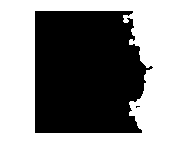

imshow(BW)

disp(tyre_p)

   218



 [BW,maskedRGBImage,] = Weed(imread("real_weed.png"));
imshow(BW)



 [BW,maskedRGBImage,lane_p ] = redlane(imread("image1.png"));

First bright pixel column red lane: 142


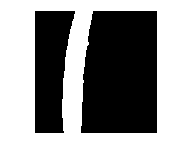

imshow(BW)

%disp(distance_from_left)

d = abs( lane_p- tyre_p);
disp(lane_p)

   142



disp(tyre_p)

   218



disp("===========================")

disp((d));

    76



disp("============================")


global match_counter;
match_counter = 1;
% Define global flags to control the movements
global red_line_detected
red_line_detected = 0;
stage_1 =0
stage_2 =0
stage_3 =0
stage_4 =0

 imagesubscriber = rossubscriber('/left_camera/image_raw', 'sensor_msgs/Image');

while true
    % Get the latest image message from the subscriber
    imgMsg = receive(imagesubscriber, 1); % Wait for 1 second for a new message
    
    % Convert the image message to an image matrix (assuming it's a sensor_msgs/Image message)
    image = readImage(imgMsg);
    
    % Detect the red line in the image (implement your red line detection algorithm here)
    % Set 'red_line_detected' to true if the red line is detected, otherwise, set it to false
    %red_line_detected = redlane(image);
     [BW,maskedRGBImage,redlinechecker ] = redlane(image);
     %if()
      red_line_detected = redlinechecker;
      disp("===========================")
      disp(red_line_detected);
     disp("===========================")
    % Perform the desired actions based on the red line detection and distance
    while (red_line_detected==0 && stage_1==0 && stage_2==0 && stage_3==0  && stage_4==0)
        stage_1=1
        straight_movement();
       
    end
    while (red_line_detected==0 &&  stage_1==1)
        straight_movement();
        disp("in loop")
        imgMsg = receive(imagesubscriber, 1);
        image = readImage(imgMsg);
        [BW,maskedRGBImage,redlinechecker] = redlane(image);
        disp(redlinechecker)
        red_line_detected = redlinechecker;

    end

   % if(red_line_detected > 0)
    %    straight_movement();
   % end
     %stage_1=1


 
    if(red_line_detected > 0)
         imgMsg = receive(imagesubscriber, 1); % Wa
        image = readImage(imgMsg);
          [BW,maskedRGBImage,p1 ] = Tyre(image);
          [BW,maskedRGBImage,p2 ] = redlane(image);
          red_line_detected  = p2
          [BW, maskedRGBImage] = Weed(image)
          d = abs(p1 - p2)
          disp(d)
          disp("=========")
        if (d) >= 40 && (d) <= 80
            straight_movement();
              disp("======00===")
        elseif (d) > 80
            left_movement();
        elseif (d) < 40
            right_movement();
        end

         Publish the detected weed positions if any weeds are detected
        if (detected_weeds==1)
            weed_locations();
        end
    end
    
    % Perform the turning_1 and turning_2 actions (assuming you have these functions)
    if (red_line_detected == 0 && stage_1 ==1)
        stage_2=1
        turning1();
        straight_movement();
        imgMsg = receive(imagesubscriber, 1); %
        image = readImage(imgMsg);
        [BW,maskedRGBImage,redlinechecker ] = redlane(image);
         red_line_detected = redlinechecker
        while (red_line_detected==0 && stage_1==1 )
            straight_movement();
            imgMsg = receive(imagesubscriber, 1); % Wa
            image = readImage(imgMsg);
            [BW,maskedRGBImage,redlinechecker ] = redlane(image);
            red_line_detected = redlinechecker

        end
    end
    
    if (red_line_detected == 0 && stage_2 ==1)
        stage_3 = 1
        turning2();
        imgMsg = receive(imagesubscriber, 1); %
        image = readImage(imgMsg);
        [BW,maskedRGBImage,redlinechecker ] = redlane(image);
         red_line_detected = redlinechecker
        while (red_line_detected==0 && stage_1==1 && stage_2 ==1)
           straight_movement();
            imgMsg = receive(imagesubscriber, 1); % Wa
            image = readImage(imgMsg);
           [BW,maskedRGBImage,redlinechecker ] = redlane(image);
             red_line_detected = redlinechecker

        end
    end

     if (red_line_detected == 0 && stage_3 ==1)
        stage_4 = 1
        stop_movement();
    end
    
    % Add any other processing or tasks you want to do here
    % The loop will continue running until you manually stop the script
    
    pause(0.1); % Add a small delay to prevent the loop from hogging the CPU
end


function concatenatedStr = matchIntAndString(match_counter, png)
    % Convert the integer to a string
    intStr = num2str(match_counter);
    
    % Concatenate the integer string with the input string
    concatenatedStr = [intStr, ".png"];
end